# Domaći zadatak iz predmeta Obrada i prepoznavanje govora

# Danica Bandović 2018/0018 

## Prvi zadatak

#### 1.Korišćenjem komercijalnog mikrofona u programskom okruženju MATLAB, snimiti govornu sekvencu u dužini od 20-ak sekundi. Sekvencu snimiti sa frekvencijom odabiranja 8 ili 10 kHz, u kojoj se nalazi desetak jasno segmentiranih reči.

Kod pomoću kog je snimljena tražena sekvenca nalazi se u ćelijama ispod. Snimljena sekvenca sačuvana je i nalazi se u okviru fajla sekvenca.wav. Za frekvenciju odabiranja odabrano je 8 kHz, snimljano je 20 sekundi i izgovoreno je 10 reči.

% inicijalizacija parametara za snimanje sekvence

fs = 8000; 
T = 1/fs;
trajanje = 20; %8 sekundi za prvi pod 3
N = trajanje*fs;
nbits = 16;
nchans = 1;

% snimanje sekvence

%x = audiorecorder(fs,nbits,nchans);
%disp('Start.')

Start.


%recordblocking(x, duration);
%disp('Stop.')

Stop.


%pustanje snimljene sekvence

%play(x)
%y = getaudiodata(x);
%sound(y, fs); %podraz. fs = 8192
%potrebno je da vrednosti y budu u intervalu (-1,1)


%audiowrite('sekvenca.wav', y, fs);


#### 2. Korišćenjem kratkovremenske energije i kratkovremenske brzine prolaska kroz nulu izvršiti određivanje početka i kraja pojedinih reči. Dobijeni rezultat prikazati grafički. Preslušati segmentirane delove zvučne sekvence i komentarisati dobijeni rezultat. (Po želji se ovaj postupak može ponoviti primenom Teager energije).

Prvo što ćemo uraditi jeste da grafički prikažemo snimljenu sekvencu, odnosno prikazaćemo odbirke snimljenog zvučnog signala u vremenu.

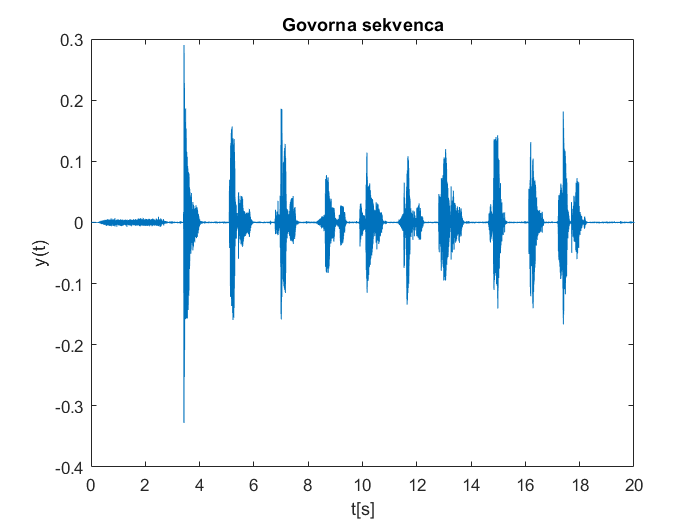

%prikaz snimljene sekvence u vremenskom domenu
[y,fs] = audioread('sekvenca.wav');

figure
    plot(0:1/fs:(length(y)-1)/fs, y);
    title('Govorna sekvenca'); xlabel('t[s]'); ylabel('y(t)');

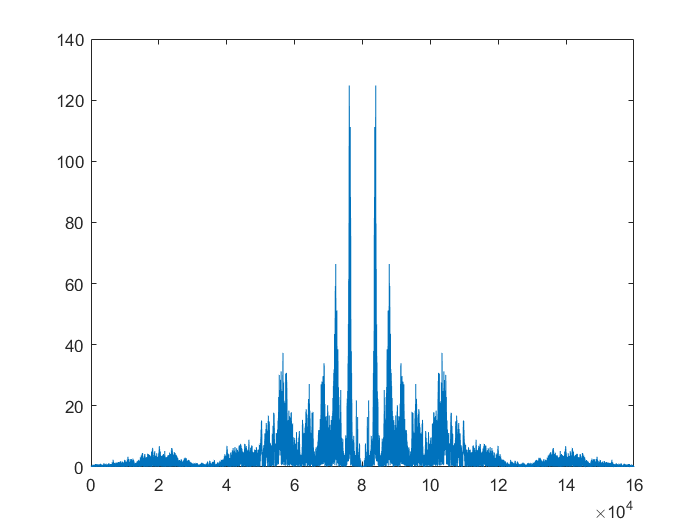

    
figure
    plot(abs(fftshift(fft(y))))

Na grafiku se primećuje 10 izdvojenih segmenata. Na početku sekvence se primećuje određeni šum koji je ili posledica mikrofona ili nekih spoljašnjih zvukova, i s obzirom da u prve dve, tri sekunde nije izgovorena nijedna reč, možemo čak i posmatrati deo sekvence tek od treće sekunde. Ono što će biti pokušano u daljem radu jeste da se pomoću kratkovremenske energije i kratkovremenskog ZCR-a izdvoje svih pojedinačnih 10 izgovorenih reči.

%POGLEDATI DA LI JE POTREBAN NF FILTAR, ALI GENERALNO NA GRAFIKU JAKO LEPO
%DELUJE DA JE ŠUM POTISNUT, SA GRAFIKA FFT-a SE NE VIDI DA POSTOJI
%DC KOMPONENTA TE NE DELUJE DA JE BILO ŠTA POTREBNO DA SE FILTRIRA


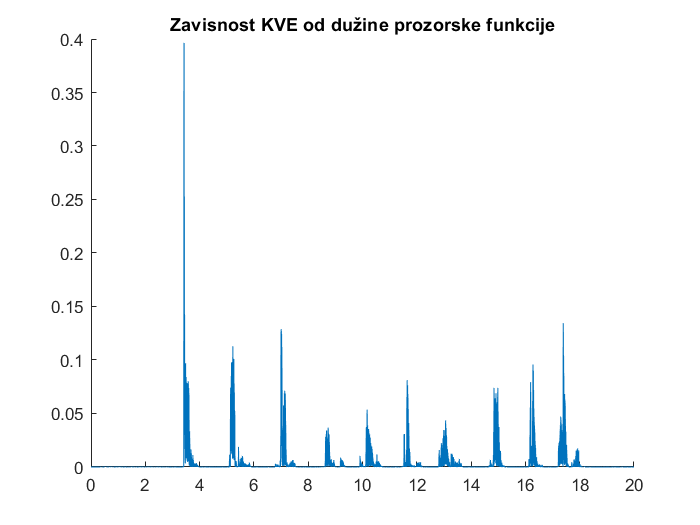

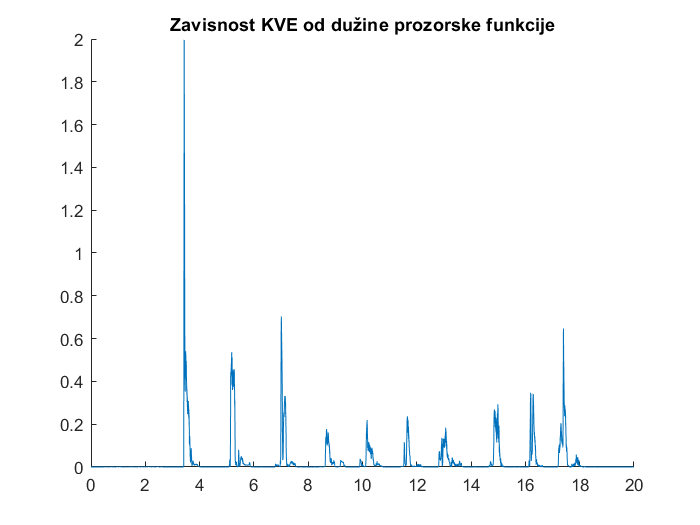

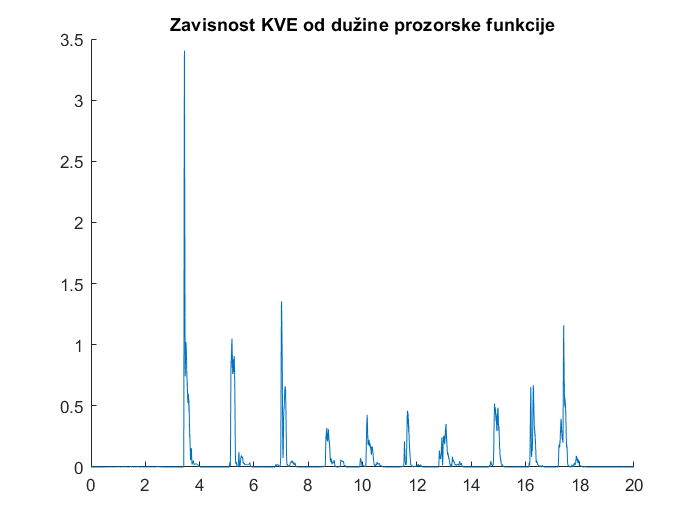

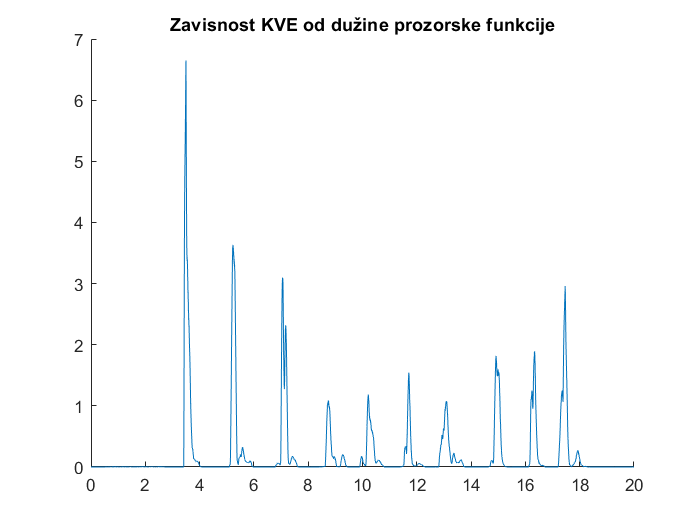

%uticaj velicine prozora, kratkovremenska energija, pravougaoni prozor
T = 1/fs;
for wl = fs*[1e-3 10e-3 20e-3 80e-3]
    E = zeros(size(y)); 
    for i = wl:length(y)
        rng = (i-wl+1) : i; 
        E(i) = sum(y(rng).^2);
    end
    figure();
    hold on;
    time = T:T:length(E)*T; 
    plot(time, E);  
    title('Zavisnost KVE od dužine prozorske funkcije')
    hold off;
    
end    

## uticaj prozorske funkcije

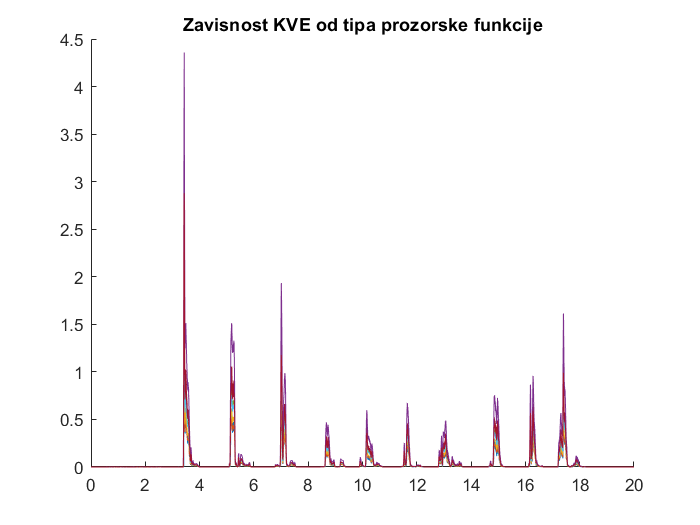

wl = fs*30e-3+1; % da bi se omogucilo da prozorske funkcije budu simetricne

for p = 1:4
    switch p
        case 1
            win = rectwin(wl); %pravougaoni prozor
        case 2 
            win = hamming(wl); %Hamingov prozor
        case 3
            win = hann(wl); %Hanov prozor
        case 4
            win = kaiser(wl, 4); % Kajzerov prozor, beta = 4
    end
    
    E = zeros(size(y)); % energija
    for i = (wl+1)/2: length(y)-wl/2
        rng = (i-(wl-1)/2) : (i+(wl-1)/2); % centrirano oko trenutnog odbirka
        E(i) = sum(y(rng).^2.*win); % suma kvadrata wl odbiraka
    end
    
    figure(4);
    title('Zavisnost KVE od tipa prozorske funkcije')
    hold on;
    time = T:T:length(E)*T;
    plot(time, E);
    hold off;
    
end

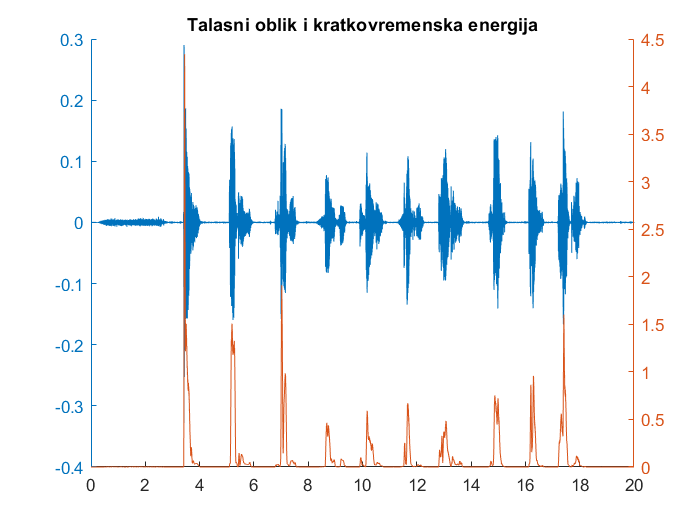

%prozor od 20ms, pravougaona prozorska fja

wl = fs*30e-3;
E = zeros(size(y));
Z = zeros(size(y));
for i= wl : length(y)
    rng = (i-wl+1):i-1;
    E(i) = sum(y(rng).^2);
    Z(i) = sum(abs(sign(y(rng+1)) - sign(y(rng))));
end
Z = Z/2/wl;

figure
    plotyy(time, y, time, E);
    title('Talasni oblik i kratkovremenska energija');

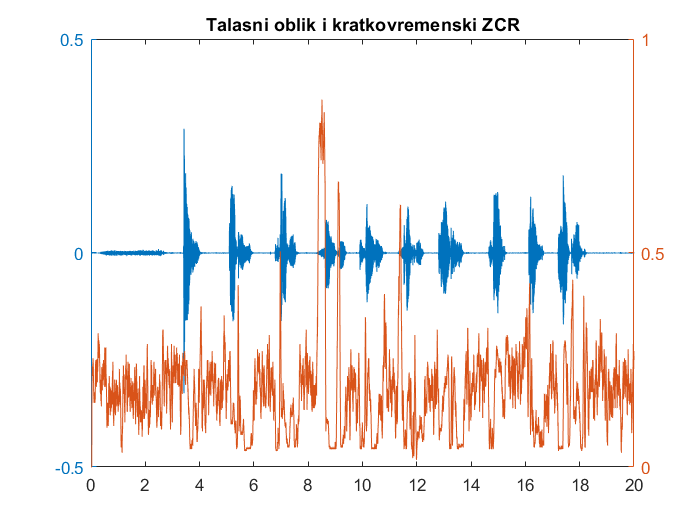

figure
    plotyy(time, y, time, Z);
    title('Talasni oblik i kratkovremenski ZCR');

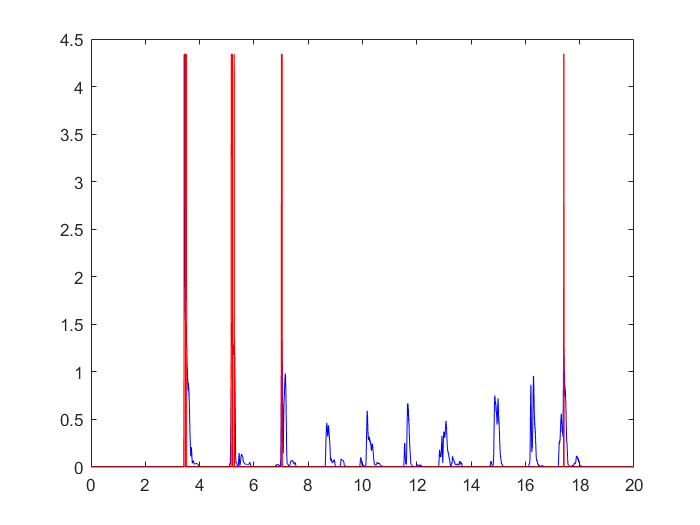

%segmentacija

ITU = 0.3*max(E);
ITL = 0.001*max(E);

pocetak_reci = [];
krajevi = [];

for i=2:length(E)
    if (E(i-1)<ITU)&&(E(i)>=ITU)
        pocetak_reci = [pocetak_reci i];
    end
    if (E(i-1)>ITU)&&(E(i)<=ITU)
        krajevi = [krajevi i];
    end
end

rec = zeros(length(E),1);
for i=1:length(pocetak_reci)
    rec(pocetak_reci(i):krajevi(i)) = max(E)*ones(krajevi(i)-pocetak_reci(i)+1,1);
end

figure
    plot(time,E,'b', time, rec, 'r');

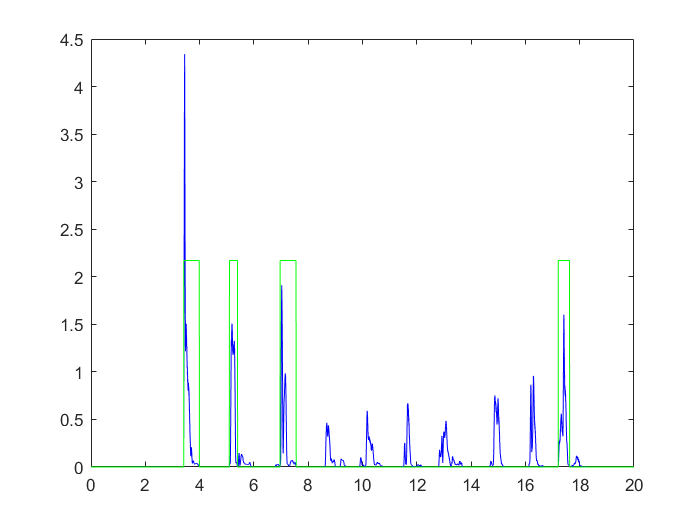

    
%prosirenje
for i=1:length(pocetak_reci)
    pomeranje = pocetak_reci(i);
    while (E(pomeranje)>ITL)
        pomeranje = pomeranje-1;
    end
    pocetak_reci(i) = pomeranje;
end

for i=1:length(krajevi)
    pomeranje = krajevi(i);
    while(E(pomeranje)>ITL)
        pomeranje = pomeranje + 1; 
    end
    krajevi(i) = pomeranje;
end

poc1(1) = pocetak_reci(1);
k = 1;
for i=2:length(pocetak_reci)
    if pocetak_reci(i)~=poc1(k)
        k=k+1;
        poc1(k) = pocetak_reci(i);
    end
end

kraj1(1) = krajevi(1);
k = 1;
for i=2:length(krajevi)
    if krajevi(i)~=kraj1(k)
        k=k+1;
        kraj1(k) = krajevi(i);
    end
end

pocetak = poc1;
kraj = kraj1;

rec = zeros(length(y),1);
for i=1:length(pocetak)
    rec(pocetak(i):kraj(i),1) = max(E)*ones(kraj(i)-pocetak(i)+1,1);
end

figure
    plot(time, E, 'b', time, rec/2, 'g');
    hold off

y(N+1:2*N) = 0;
y1 = 8*y;
y2 = 0.2*y;
y3 = -5*y;
y4 = -0.2*y;

sound(y1,fs);
pause(6);
sound(y2,fs);
pause(12);

sound(y3,fs);
pause(20);
sound(y4,fs);

y5 = y(end:-1:1);
sound(y5,fs);

factor=3;
ysporo = zeros(1,factor*length(y));

for k = factor:factor:length(ysporo)
    ysporo(k:k+factor-1) = y(k/factor);
end

sound(ysporo)

ybrzo = zeros(1,floor(length(y)/factor))

for k=1:length(ybrzo)
    ybrzo(k) = y(k*factor)
end
sound(ybrzo)

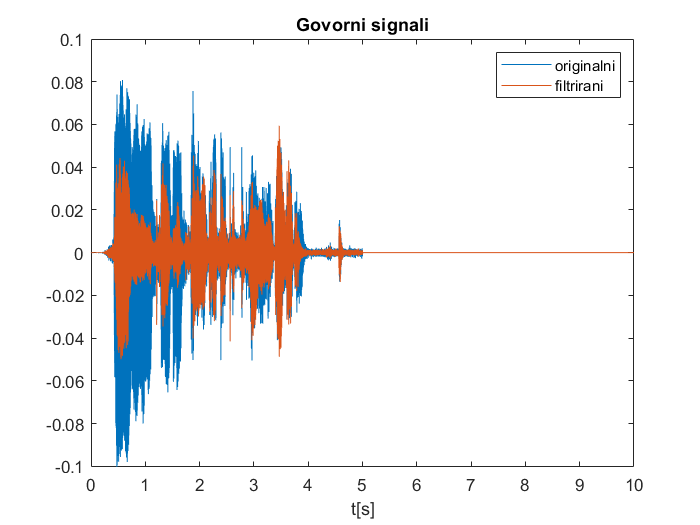

nord = 6;
Wn = [300 3400]/(fs/2);
[b,a] = butter(nord, Wn, 'bandpass');
yf = filter(b,a,y);

figure()
    plot(0:1/fs:(length(y)-1)/fs,y);
    hold on;
    plot(0:1/fs:(length(y)-1)/fs, yf);
    title('Govorni signali'); xlabel('t[s]'); legend('originalni', 'filtrirani');

    
sound(yf,fs);